# SNW_A4CHK_WRK_BISEC_VEC Small Solution Analysis

This is the example vignette for function: [**snw_a4chk_wrk_bisec_vec**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/splanner/snw_a4chk_wrk_bisec_vec.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for the V(states, check) for individuals working. Small Solution, bisect exact.

## Test SNW_A4CHK_WRK_BISEC_VEC Defaults Small

Call the function with defaults.

mp_params = snw_mp_param('default_small');
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = false;
mp_controls('bl_timer') = true;
[V_ss,~,~,~] = snw_vfi_main_bisec_vec(mp_params, mp_controls);

Elapsed time is 0.913139 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_test


welf_checks = 2;
[V_W, exitflag_fsolve] = snw_a4chk_wrk_bisec_vec(welf_checks, V_ss, mp_params, mp_controls);

SNW_A4CHK_WRK: Finished Age Group:1 of 18
SNW_A4CHK_WRK: Finished Age Group:2 of 18
SNW_A4CHK_WRK: Finished Age Group:3 of 18
SNW_A4CHK_WRK: Finished Age Group:4 of 18
SNW_A4CHK_WRK: Finished Age Group:5 of 18
SNW_A4CHK_WRK: Finished Age Group:6 of 18
SNW_A4CHK_WRK: Finished Age Group:7 of 18
SNW_A4CHK_WRK: Finished Age Group:8 of 18
SNW_A4CHK_WRK: Finished Age Group:9 of 18
SNW_A4CHK_WRK: Finished Age Group:10 of 18
SNW_A4CHK_WRK: Finished Age Group:11 of 18
SNW_A4CHK_WRK: Finished Age Group:12 of 18
SNW_A4CHK_WRK: Finished Age Group:13 of 18
SNW_A4CHK_WRK: Finished Age Group:14 of 18
SNW_A4CHK_WRK: Finished Age Group:15 of 18
SNW_A4CHK_WRK: Finished Age Group:16 of 18
SNW_A4CHK_WRK: Finished Age Group:17 of 18
SNW_A4CHK_WRK: Finished Age Group:18 of 18
Elapsed time is 0.796642 seconds.
Completed SNW_A4CHK_WRK;welf_checks=2;TR=0.0017225;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_test
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAM

mn_V_W_gain_check = V_W - V_ss;

## Small Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids: 
age_grid = [19, 22:5:97, 100];
agrid = mp_params('agrid')';
eta_H_grid = mp_params('eta_H_grid')';
eta_S_grid = mp_params('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'Hshock', eta_H_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Difference in V and V with Check

The difference between V and V with Check, marginal utility gain given the check.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log

#### MEAN(MN_V_GAIN_CHECK(A,Z))

Tabulate value and policies along savings and shocks:

% Set
ar_permute = [1,4,5,6,3,2];
% Value Function
st_title = ['MEAN(MN_V_W_GAIN_CHECK(A,Z)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_v = ff_summ_nd_array(st_title, mn_V_W_gain_check, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_W_GAIN_CHECK(A,Z)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_Hshock__0_91976    mean_Hshock__0_45988    mean_Hshock_0    mean_Hshock_0_45988    mean_Hshock_0_91976
    _____    ________    ____________________    ____________________    _____________    ___________________    ___________________

      1             0           0.035156                0.025394            0.020715            0.018309               0.017066     
      2      0.013744           0.026284                0.019092            0.015317             0.01317               0.012001     
      3       0.10995           0.015927                0.011873           0.0090565           0.0074172              0.0063905     
    

Graph Mean Values:

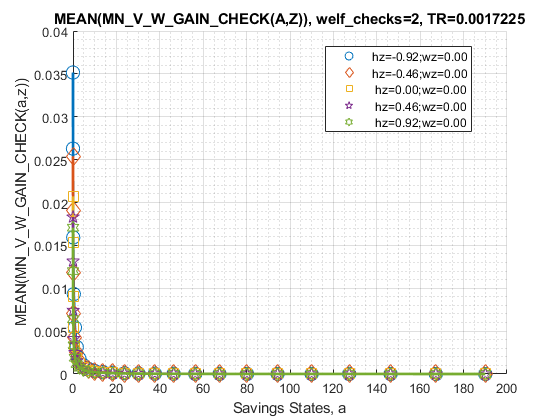

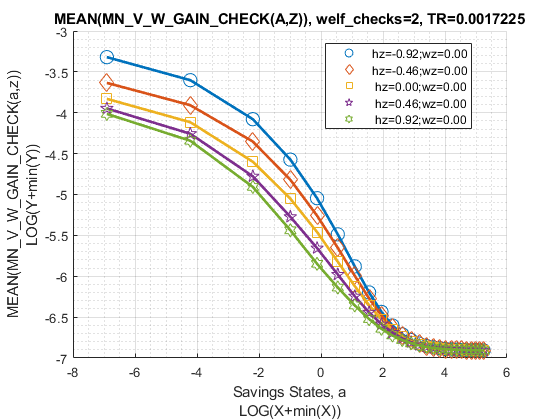

st_title = ['MEAN(MN\_V\_W\_GAIN\_CHECK(A,Z)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_W\_GAIN\_CHECK(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
st_title = ['MEAN(MN_V_W_GAIN_CHECK(KM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_v = ff_summ_nd_array(st_title, mn_V_W_gain_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_W_GAIN_CHECK(KM,J)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___

Graph Mean Values:

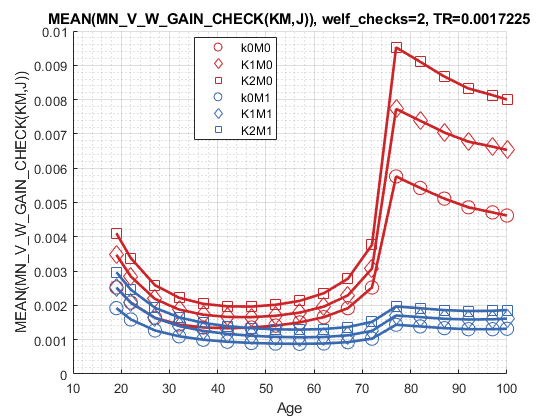

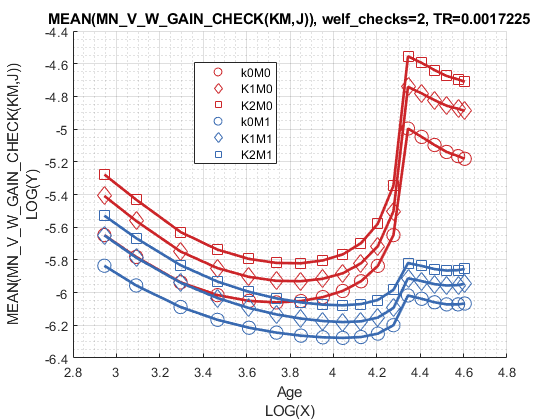

st_title = ['MEAN(MN\_V\_W\_GAIN\_CHECK(KM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_W\_GAIN\_CHECK(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(VAL(EM,J)), MEAN(AP(EM,J)), MEAN(C(EM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
st_title = ['MEAN(MN_V_W_GAIN_CHECK(EM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_v = ff_summ_nd_array(st_title, mn_V_W_gain_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_W_GAIN_CHECK(EM,J)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    _____

Graph Mean Values:

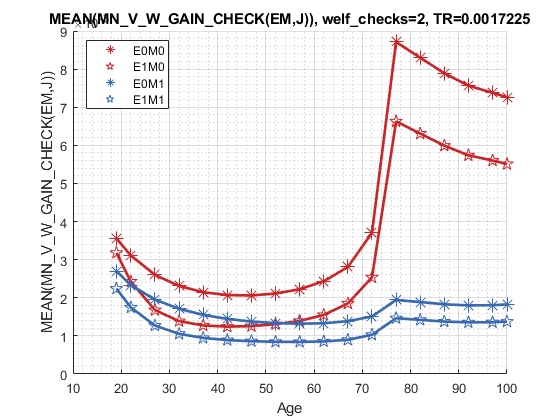

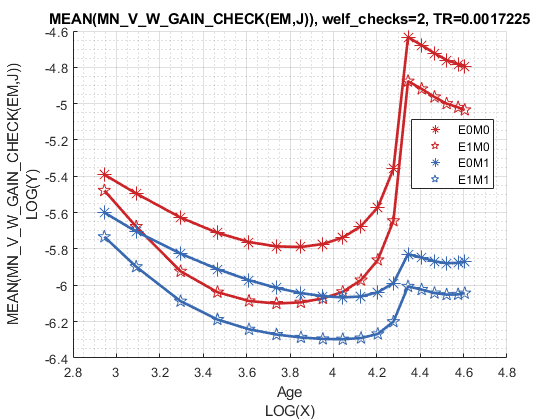

st_title = ['MEAN(MN\_V\_W\_GAIN\_CHECK(EM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_W\_GAIN\_CHECK(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);